Before using this: 

consider making a names list file

split data samples so we have test and training sets

Start fresh, and load all the data

If we have to manipulate or fix up every data set, we'll do that in this loop too

Transform data sets into usable massive vectors while mashing vectors into covariance matrix

clear all
load allData.mat
dataMatrix = abs(dataMatrix);
testMatrix = abs(testMatrix);

Eigenstuff time. We have the vectors matrix, and will pull out the eigen vectors, eigen values, and more eigen vectors I think. U is the matrix of eigenvectors.

Then, make a matrix of coefficients.

[U,S,V] = svd(dataMatrix,'econ');
U = abs(U(:,2:end));
coeffMatrix = U'*dataMatrix;
sizeN = length(coeffMatrix);

A good idea to plot one eigenvector to see if it makes sense

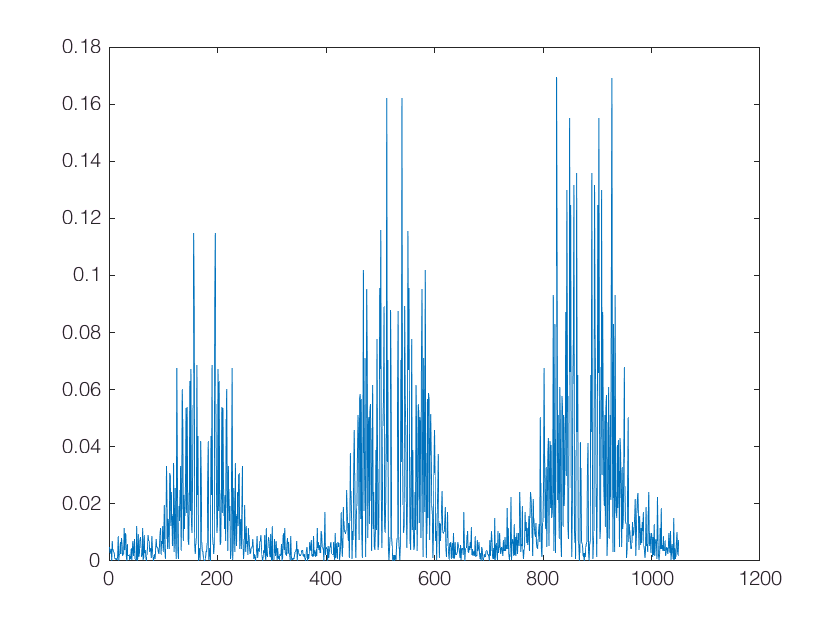

eigenVictim = U(:,1);
hold off; clf;
plot(abs(eigenVictim));

Test a data

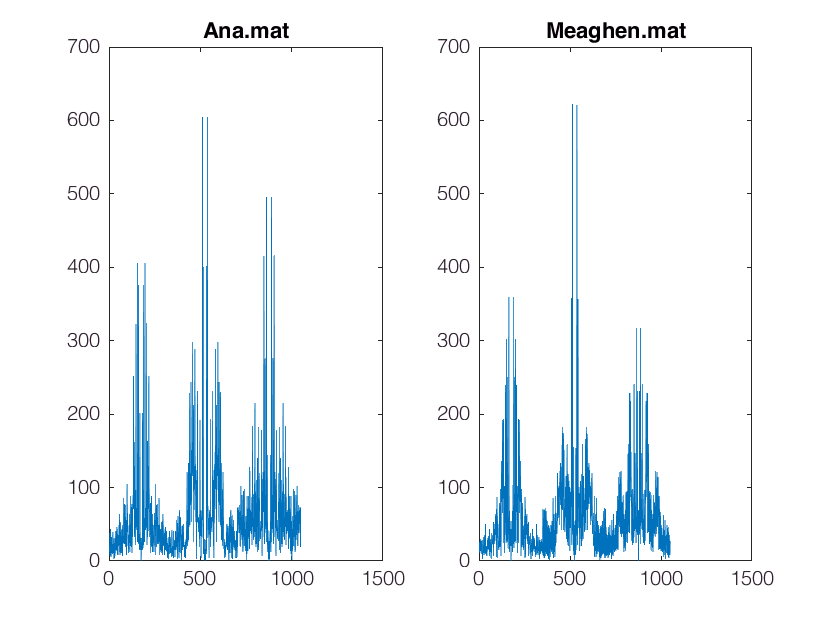

pick = 6;
testGait = testMatrix(:,pick);
testAnswer = nameList(pick);
testCoeff = U'*testGait;

% find closest match index for just the one gait
differences = zeros(1,sizeN);
for i = 1:sizeN
    differences(i) = norm(coeffMatrix(:,i)-testCoeff);
end
[minComparison, indexGuessed] = min(differences);
subplot(1,2,1)
plot(abs(testGait));
title(testAnswer)
subplot(1,2,2)
plot(abs(dataMatrix(:,indexGuessed)));
title(nameList(indexGuessed));

amirite = zeros(1,sizeN);
for pick = 1:sizeN;
    differences = zeros(1,sizeN);
    testGait = testMatrix(:,pick);
    testAnswer = nameList(pick);
    testCoeff = U'*testGait;
    for i = 1:sizeN
        differences(i) = norm(coeffMatrix(:,i)-testCoeff);
    end
    [minComparison, indexGuessed] = min(differences);
    amirite(pick) = isequal(pick,indexGuessed);
end
mean(amirite)

ans = 0.4643

amirite

amirite =      0     0     1     1     1     0     1     1     0     1     0     0     0     0     0     1     1     1     0     0     1     0     0     0     1     0     1     1
